# Perform Landmark SLAM Using Extended Kalman Filter

Load a race track data set that contains the initial vehicle state, initial vehicle state covariance, process noise covariance, control input, time step size, measurement, measurement covariance, and validation gate values.

load("racetrackDataset.mat","initialState","initialStateCovariance", ...
     "processNoise","controllerInputs","timeStep", ...
     "measurements","measCovar","validationGate");

Create an `ekfSLAM` object with initial state, initial state covariance, and process noise.

ekfSlamObj = ekfSLAM("State",initialState, ...
                     "StateCovariance",initialStateCovariance, ...
                     "ProcessNoise",processNoise);

Initialize a variable to store the pose.

storedPose = nan(size(controllerInputs,1)+1,3);
storedPose(1,:) = ekfSlamObj.State(1:3);

Predict the state using the control input and time step size for the state transition function. Then, correct the state using the data of the observed landmarks, measurement covariance, and validation gate for the data association function.

for count = 1:size(controllerInputs,1)
    % Predict the state
    predict(ekfSlamObj,controllerInputs(count,:),timeStep);
 
    % Get the landmarks in the environment
    observedLandmarks = measurements{count};
 
    % Correct the state
    if ~isempty(observedLandmarks)
        correct(ekfSlamObj,observedLandmarks, ...
                measCovar,validationGate);
    end
  
    % Log the estimated pose
    storedPose(count+1,:) = ekfSlamObj.State(1:3);
end

Visualize the created map.

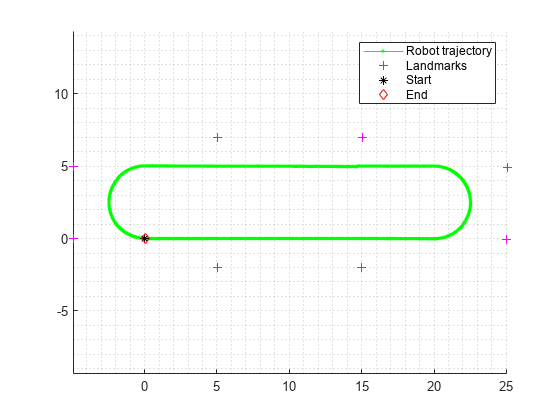

fig = figure;
figAx = axes(fig);
axis equal
grid minor
hold on
plot(figAx,storedPose(:,1),storedPose(:,2),"g.-")
landmarks = reshape(ekfSlamObj.State(4:end),2,[])';
plot(figAx,landmarks(:,1),landmarks(:,2),"m+")
plot(figAx,storedPose(1,1),storedPose(1,2),"k*")
plot(figAx,storedPose(end,1),storedPose(end,2),"rd")
legend("Robot trajectory","Landmarks","Start","End")

*Copyright 2021 The MathWorks, Inc.*